# **APF: Attractive force in W Space**

**Attractive force on control points**

[filepath,~,~] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(filepath);
addpath(fullfile(filepath,'myfunc'),'-begin')

### Model, Control Points and Obstacles

w = 15; h = 2;
ncptw = 15;
ncpth = 4;
ncptb = 10;

cpt1 = [linspace(-w,w,ncptw) ; -ones(1,ncptw)*h];
cpt2 = [ones(1,ncpth)*w ; linspace(-h,h,ncpth)];
cpt3 = [linspace(w,-w,ncptw) ; ones(1,ncptw)*h];
cpt4 = [-ones(1,ncpth)*w ; linspace(h,-h,ncpth)];
cpt5 = [linspace(0,-w,ncptb);linspace(-h,0,ncptb)];
ctrlpt_0 = [cpt1,cpt2(:,2:end-1),cpt3,cpt4(:,2:end-1)];
n_controlpt = size(ctrlpt_0,2);

car0 = [-1,-1;1,-1;1,1;-1,1]'.*[w;h];

**Obstacles**

C_obs{1} = [5 55 30; 70 70 90];
C_obs{2} = [80 90 90 80;70 70 110 110];
C_obs{3} = [30 60 60 30;20 20 50 50];
C_obs{4} = [cosd(linspace(-180,65,10));sind(linspace(-180,65,10))]*12.5+[93;45];

### Parameters

qI = [8;125;90*pi/180]; % Initial States, [x,y,theta]
qG = [105;10;0*pi/180]; % Goal States

max_iter = 1000;
coeff_rep = 20000;
coeff_att = [1;1]*1;

% parameters for APF force
rad_rep = 20;
maxdist = 500;
max_step = [2,2,5/180*pi]'.*[-1,1];

stepsize = [0.0002;0.0002;0.00001];
eps = [0.1;2*pi/180];

carI = HomTran2d(qI(3),qI(1:2),car0);
ctrlpt_I = HomTran2d(qI(3),qI(1:2),ctrlpt_0);
carG = HomTran2d(qG(3),qG(1:2),car0);
ctrlpt_G = HomTran2d(qG(3),qG(1:2),ctrlpt_0);
approach_coeff = 10/100;

### Simulation

**Plot Initial Pos**

f = figure;
pIG(1) = patch(carI(1,:),carI(2,:),[0 0.4470 0.7410]); hold on
pIG(2) = patch(carG(1,:),carG(2,:),[0.8500 0.3250 0.0980]); hold on
[pIG(:).FaceAlpha] = deal(0.3);
for i = 1:length(C_obs)
    patch(C_obs{i}(1,:),C_obs{i}(2,:),[0.9290 0.6940 0.1250]); hold on
end
grid on; axis equal
pa = quiver(NaN,NaN,NaN,NaN,'Color',[0.4660 0.6740 0.1880],'LineWidth',1); hold on
pr = quiver(NaN,NaN,NaN,NaN,'Color','b','LineWidth',1); hold on
pctrl = plot(NaN,NaN,'.r','MarkerSize',8); hold on
pp = plot(NaN,NaN,'-k','LineWidth',1); hold on
xlim([0,130]); ylim([-10,150]);
legend([pr,pa,pctrl,pp],{'repulse','attract','ctrl pts','next state'},'Location','northeast')
title('Attractive Force applied on Control Points in W-Space')
set(f,'Units','normalized','Position',[0,0,0.5,0.7]);

**APF Loop**

dpos0 = norm(qG(1:2)-qI(1:2));
dag0 = abs(qG(3)-qI(3));
dq_ref = [dpos0;pi];
coeff_att0 = coeff_att;

qC = qI;
Tq_rep = NaN(3,n_controlpt);
Tq_att = NaN(3,n_controlpt);
qs = NaN(3,max_iter);
v = zeros(size(qI));
momentum = 0.5;

for i = 1:max_iter
    qs(:,i) = qC;

    % Break the Loop
    dpos = norm(qG(1:2)-qC(1:2));
    dag = abs(qG(3)-qC(3));
    if dpos<=eps(1) && abs(dag-round(dag/pi)*pi)<=eps(2)
        break;
    end

    % Increase learning rate for final steps
    x = [dpos/dq_ref(1);abs(dag-round(dag/pi)*pi)];
    if all(x<=approach_coeff)
        coeff_att = increase_k(approach_coeff,coeff_att0,5*coeff_att0,x);
    else
        coeff_att = coeff_att0;
    end

    % Control points
    ctrlpt_c = HomTran2d(qC(3),qC(1:2),ctrlpt_0);

**Calculate repulsive and attractive force**

    J = jacobSE2(ctrlpt_0(1,:),ctrlpt_0(2,:),qC(3));

    for j = 1:n_controlpt

        [closestpt,closestdist] = closestpt2Shape2d(ctrlpt_c(:,j),C_obs);

        % repulsive force for each obstacle
        F = dUrepFunc(ctrlpt_c(:,j),coeff_rep,rad_rep,closestdist,closestpt);

        % repulsive force for each control point
        F_rep = sum(F,2);
        Tq_rep(:,j) = J(:,:,j)'*F_rep;

        % attractive force
        F_att = dUattFunc(ctrlpt_c(:,j),ctrlpt_G(:,j),coeff_att,maxdist);
        Tq_att(:,j) = J(:,:,j)'*F_att;
        
    end

    % repulsive/attractive force for all control point
    Tq_rep_all = sum(Tq_rep,2);
    Tq_att_all = sum(Tq_att,2);

**Calculate Step**

    dq = stepsize .* (Tq_rep_all+Tq_att_all);
    dq = bound2range(dq,max_step);
    v = momentum*v+(1-momentum)*dq;
    qC = qC-v;

**Calculate Current pos for the car**

    car = HomTran2d(qC(3),qC(1:2),car0);
    car = ptsloop(car);
    ctrlpt_c_p = ptsloop(ctrlpt_c);

**Plot**

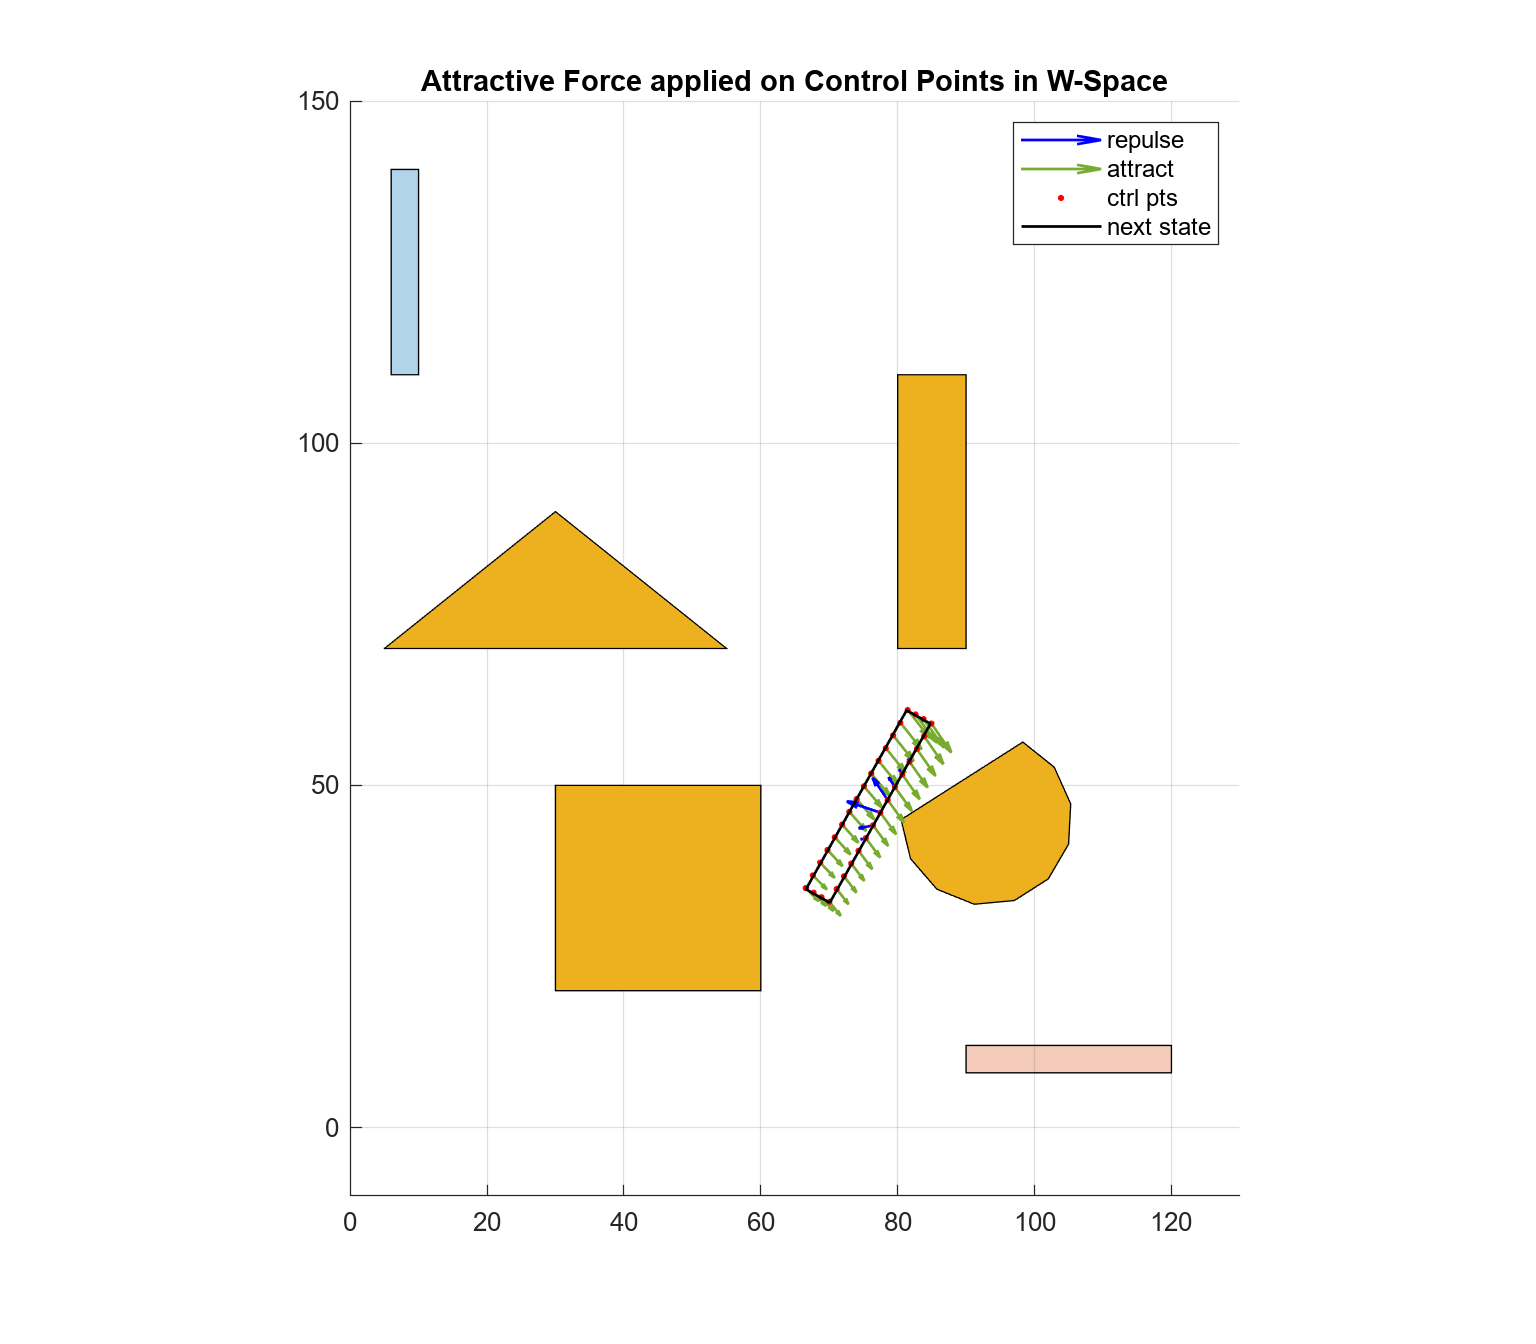

    pp.XData = car(1,:);
    pp.YData = car(2,:);
    pctrl.XData = ctrlpt_c_p(1,:);
    pctrl.YData = ctrlpt_c_p(2,:);
    pr.XData = ctrlpt_c(1,:);
    pr.YData = ctrlpt_c(2,:);
    pr.UData = -Tq_rep(1,:);
    pr.VData = -Tq_rep(2,:);
    pa.XData = ctrlpt_c(1,:);
    pa.YData = ctrlpt_c(2,:);
    pa.UData = -Tq_att(1,:);
    pa.VData = -Tq_att(2,:);
    drawnow;
end

function F = dUrepFunc(q,coeff_rep,rad_rep,closestdist,closestpt)
ind = closestdist<rad_rep;
F = zeros(length(q),length(closestdist));
if any(ind)
F(:,ind) = coeff_rep*(1/rad_rep-1./closestdist(ind))./closestdist(ind).^3.*(q-closestpt(:,ind));
end
end

function F = dUattFunc(q,qG,coeff_att,maxdist)
dq = q-qG;
dist = norm(dq);
if dist<=maxdist
    F = coeff_att.*dq;
else
    F = maxdist*coeff_att.*dq/dist;
end
end